# Joule Main

clear;clc;close all;
cd('D:/Works/Analysis/Joule');
addpath(genpath('matnwb'));

generateCore();

disp("Toolbox setup done.");

Toolbox setup done.


cd('D:/Works/Analysis/Joule');
addpath(genpath('matnwb'));

generateCore();
disp("Toolbox setup done.");

Toolbox setup done.


nwbPath = "data/";
% y = jPassiveGLOSignals(nwbPath, 10, "muae", 5, 2, 0, 1, 1, 7);

nwbPath = "data/";
nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));
nwbFile = nwbPath + nwbFiles{10};

nwb = nwbRead(nwbFile);
disp("Loaded" + nwbFile);

Loadeddata/sub-C31o_ses-230630.nwb


% jGLOPassiveTrialCounts(nwb);

## RF mapping

-> 2 Probes detected in sub-V198_ses-230525
-->Area V1,V2


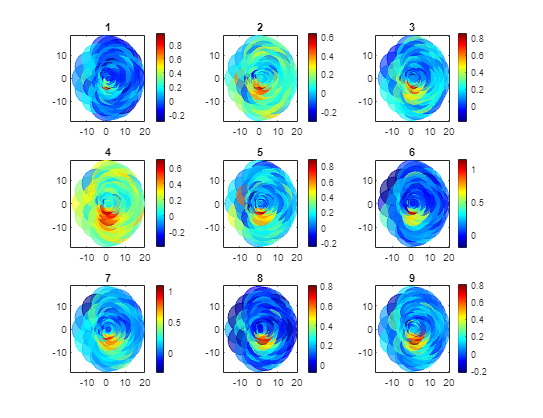

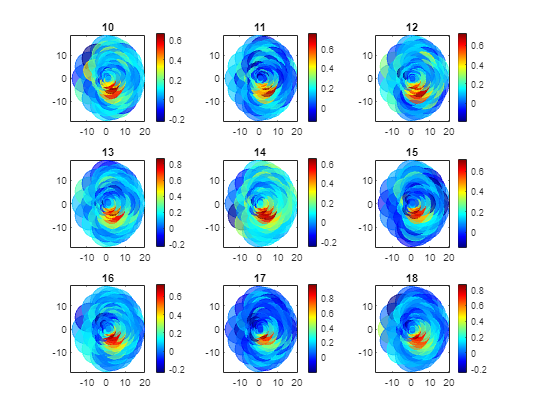

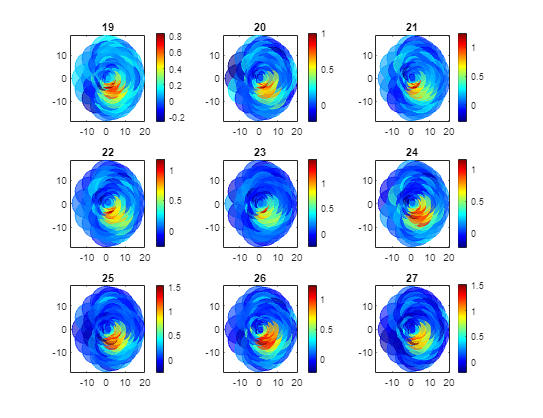

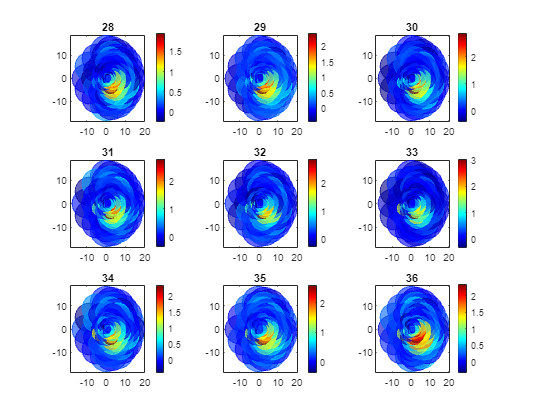

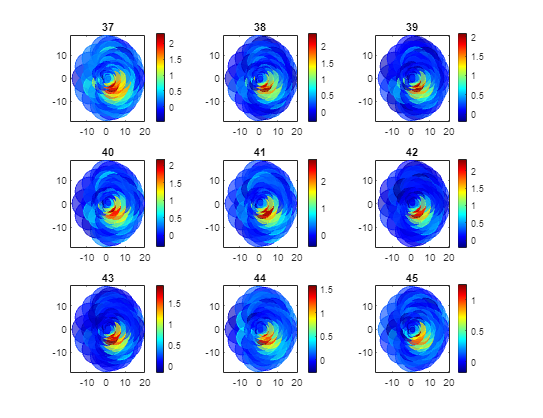

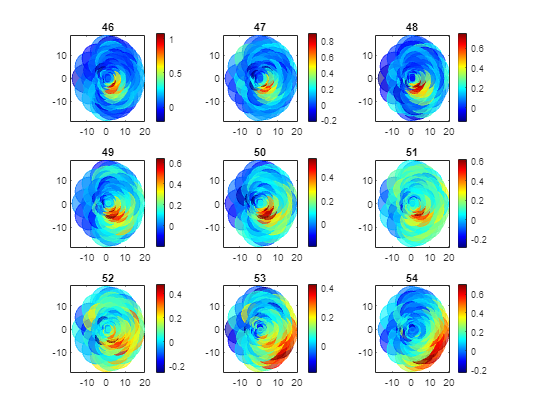

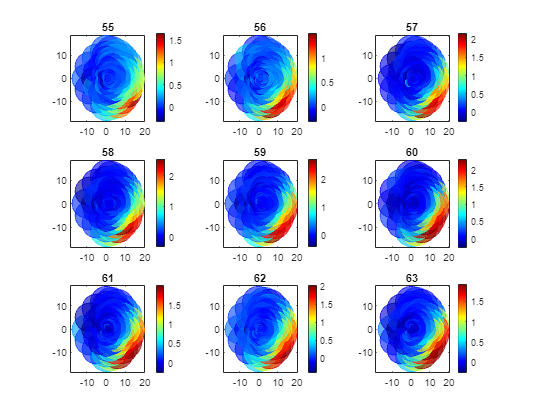

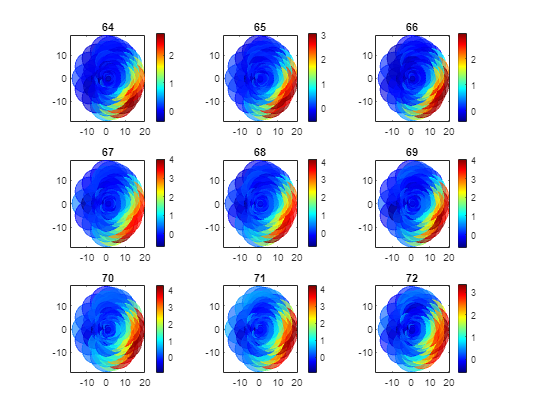

-->Area V3d, V3a


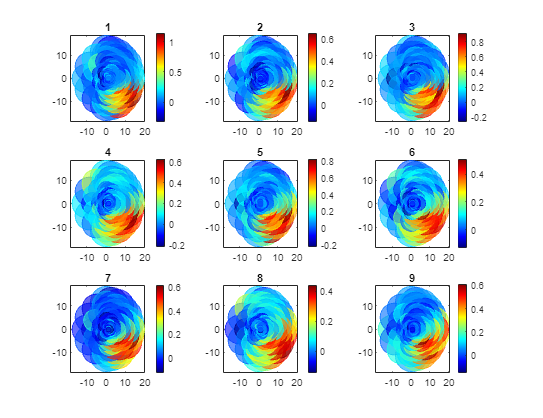

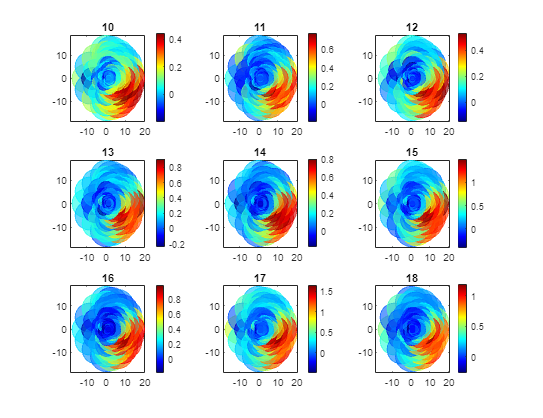

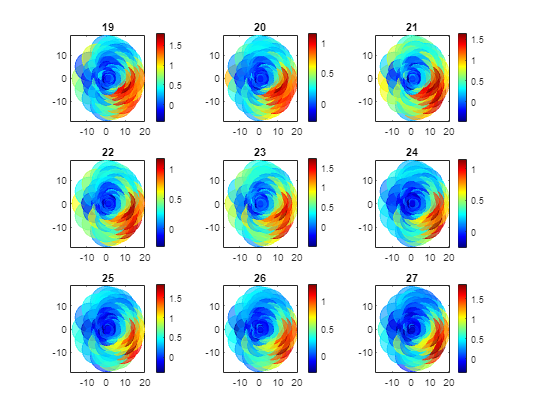

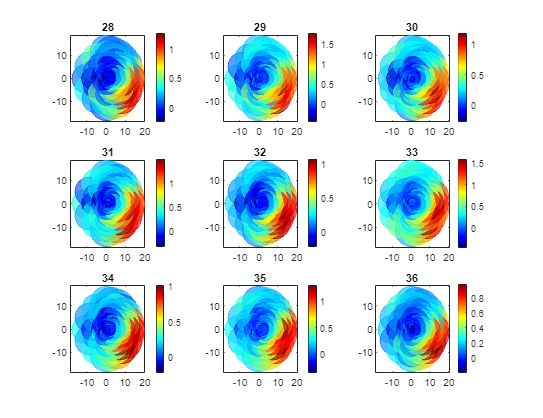

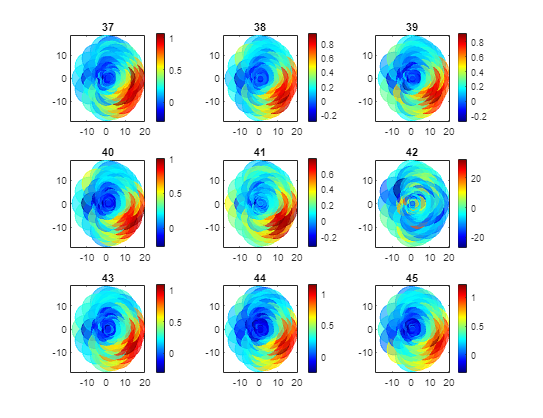

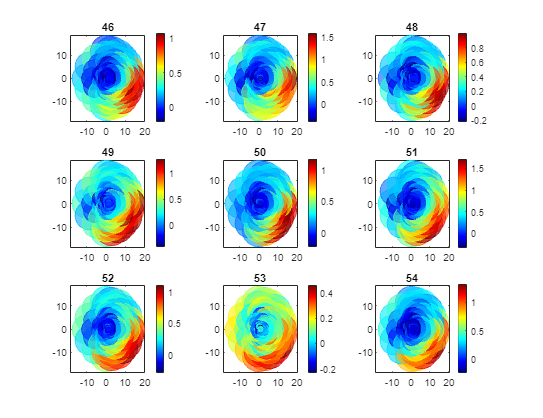

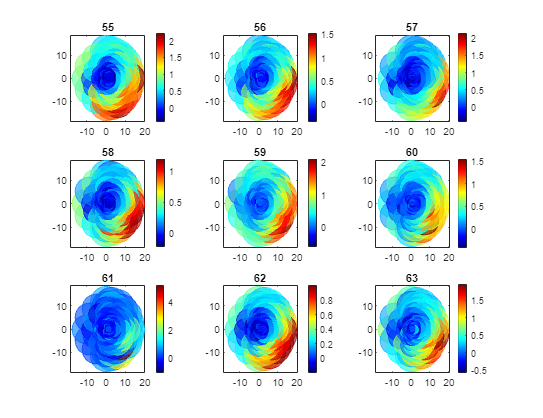

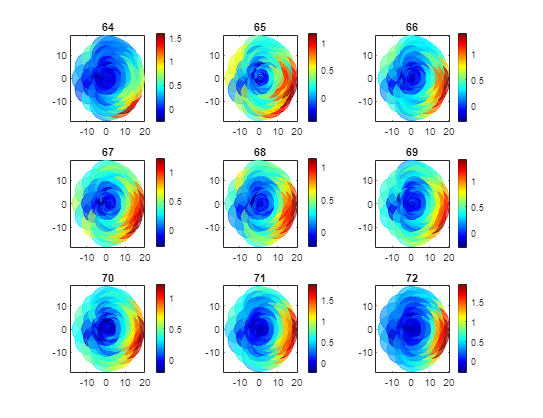

close all;
ReceptiveFieldMap(nwb);

lfps = nwb.acquisition.get("probe_0_lfp").electricalseries.get("probe_0_lfp_data").data(:, :);
muas = nwb.acquisition.get("probe_0_muae").electricalseries.get("probe_0_muae_data").data(:, :);

close all;
cd('D:/Works/Analysis/Joule');
addpath(genpath('matnwb'));

generateCore();
disp("Toolbox setup done.");

Toolbox setup done.


nwbPath = "data/";
y = PassiveGLOSignals(nwbPath, 3, "muae", 5, 2, 0, 1, 1, 7);

>Starting
->Median filter is on with channel window width = 1, time window width 7
->Single process data/sub-V198_ses-230525.nwb
->Processing trials - This function is ONLY for passive mode. For active, use <ActiveGLOSignals.m>
-->B1:Local(C-habexp) 15
-->B1:Local(C-habexp) 27
-->B1:Local(C-habexp) 39
-->B1:Local(C-habexp) 51
-->B1:Local(C-habexp) 63
-->B1:Local(C-habexp) 75
-->B1:Local(C-habexp) 87
-->B1:Local(C-habexp) 99
-->B1:Local(C-habexp) 111
-->B1:Local(C-habexp) 132
-->B1:Local(C-habexp) 144
-->B1:Local(C-habexp) 162
-->B1:Local(C-habexp) 174
-->B1:Local(C-habexp) 186
-->B1:Local(C-habexp) 204
-->B1:Local(C-habexp) 216
-->B1:Local(C-habexp) 228
-->B1:Local(C-habexp) 245
-->B1:Local(C-habexp) 257
-->B1:Local(C-habexp) 274
-->B1:Local(C-habexp) 290
-->B1:Local(C-habexp) 302
-->B1:Local(C-habexp) 322
-->B1:Local(C-habexp) 334
-->B1:Local(C-habexp) 351
-->B1:Local(C-habexp) 369
-->B1:Local(C-habexp) 381
-->B1:Local(C-habexp) 393
-->B1:Local(C-habexp) 411
-->B1:Local(C-habexp) 423


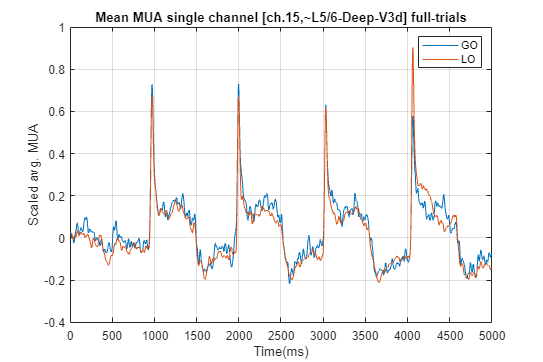

figure("Position", [0 0 1500 1000]);
ch = 15;
plot(squeeze(mean(y.B2G(:, ch, 1001:6000), 1)), "DisplayName", "GO");
hold("on");
plot(squeeze(mean(y.B2L(:, ch, 1001:6000), 1)), "DisplayName", "LO");
legend;xlabel("Time(ms)");ylabel("Scaled avg. MUA");
title("Mean MUA single channel [ch." + num2str(ch) + ",~L5/6-Deep-V3d] full-trials");
grid("on");

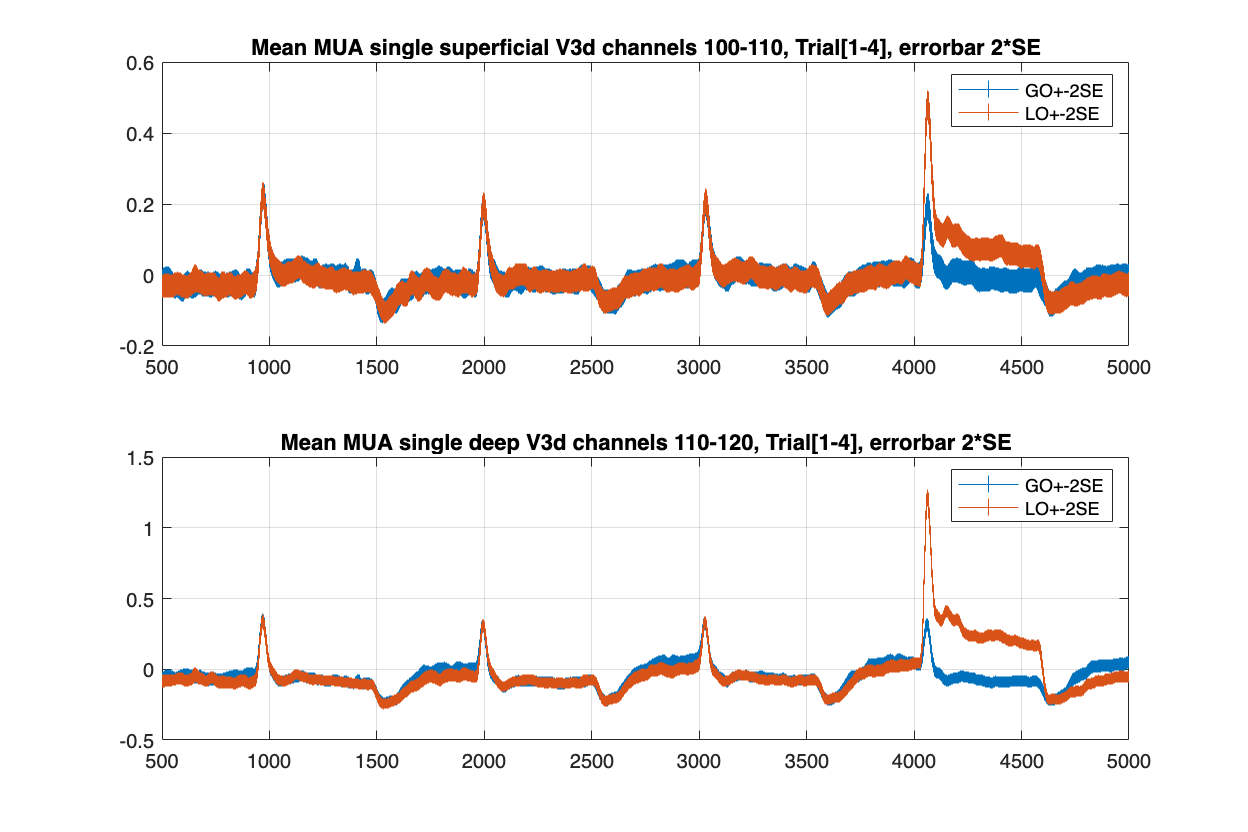

figure("Position", [0 0 1500 1000]);

chs = 100:110;
subplot(2, 1, 1);
x1 = 501:5000;
y1 = squeeze(mean(mean(y.x1(:, chs, 1501:6000), 1), 2));
e1 = 2*squeeze(mean(std(y.x1(:, chs, 1501:6000), 1), 2))/sqrt(size(y.x1, 1));
errorbar(x1, y1, e1, "DisplayName", "GO+-2SE", "CapSize", 0);

hold("on");

x2 = 501:5000;
y2 = squeeze(mean(mean(y.x2(:, chs, 1501:6000), 1), 2));
e2 = 2*squeeze(mean(std(y.x2(:, chs, 1501:6000), 1), 2))/sqrt(size(y.x2, 1));
errorbar(x2, y2, e2, "DisplayName", "LO+-2SE", "CapSize", 0);

legend;grid;
title("Mean MUA single superficial V3d channels " + num2str(chs(1)) + "-" + num2str(chs(end)) + ", Trial[1-4], errorbar 2*SE");
xlim([500 5000]);

chs = 110:120;
subplot(2, 1, 2);
x1 = 501:5000;
y1 = squeeze(mean(mean(y.x1(:, chs, 1501:6000), 1), 2));
e1 = 2*squeeze(mean(std(y.x1(:, chs, 1501:6000), 1), 2))/sqrt(size(y.x1, 1));
errorbar(x1, y1, e1, "DisplayName", "GO+-2SE", "CapSize", 0);

hold("on");

x2 = 501:5000;
y2 = squeeze(mean(mean(y.x2(:, chs, 1501:6000), 1), 2));
e2 = 2*squeeze(mean(std(y.x2(:, chs, 1501:6000), 1), 2))/sqrt(size(y.x2, 1));
errorbar(x2, y2, e2, "DisplayName", "LO+-2SE", "CapSize", 0);

legend;grid;
title("Mean MUA single deep V3d channels " + num2str(chs(1)) + "-" + num2str(chs(end)) + ", Trial[1-4], errorbar 2*SE");
xlim([500 5000]);

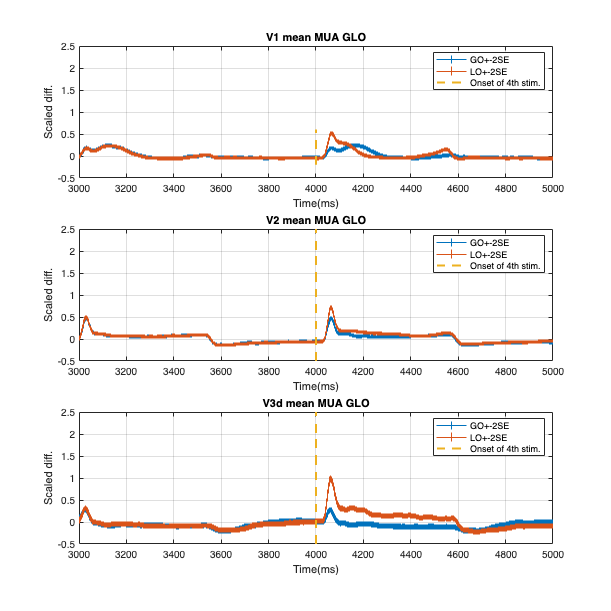

figure("Position", [0 0 1400 1400]);

chs = 5:25;

subplot(3, 1, 1);

x1 = 3001:5000;
y1 = squeeze(mean(mean(y.x1(:, chs, 4001:6000), 1), 2));
% y1 = y1 / max(y1);
e1 = 2*squeeze(mean(std(y.x1(:, chs, 4001:6000), 1), 2))/sqrt(size(y.x1, 1));
errorbar(x1, y1, e1, "DisplayName", "GO+-2SE", "CapSize", 0);

xlabel("Time(ms)");ylabel("Scaled diff.");
hold("on");

x2 = 3001:5000;
y2 = squeeze(mean(mean(y.x2(:, chs, 4001:6000), 1), 2));
% y2 = y2 / max(y1);
e2 = 2*squeeze(mean(std(y.x2(:, chs, 4001:6000), 1), 2))/sqrt(size(y.x2, 1));
errorbar(x2, y2, e2, "DisplayName", "LO+-2SE", "CapSize", 0);

plot(ones(1, 10)*4000, linspace(-.2, .6, 10), "LineWidth", 2, "LineStyle", "--", "DisplayName", "Onset of 4th stim.");

xlabel("Time(ms)");ylabel("Scaled diff.");
legend;grid;
title("V1 mean MUA GLO");
% title("Mean LFP single channel " + num2str(chs(1)) + "-" + num2str(chs(end)) + ", Trial[3-4], errorbar 2*SE");
xlim([3000 5000]);
ylim([-.5 2.5]);

chs = 25:50;

subplot(3, 1, 2);

x1 = 3001:5000;
y1 = squeeze(mean(mean(y.x1(:, chs, 4001:6000), 1), 2));
% y1 = y1 / max(y1);
e1 = 2*squeeze(mean(std(y.x1(:, chs, 4001:6000), 1), 2))/sqrt(size(y.x1, 1));
errorbar(x1, y1, e1, "DisplayName", "GO+-2SE", "CapSize", 0);

xlabel("Time(ms)");ylabel("Scaled diff.");
hold("on");

x2 = 3001:5000;
y2 = squeeze(mean(mean(y.x2(:, chs, 4001:6000), 1), 2));
% y2 = y2 / max(y2);
e2 = 2*squeeze(mean(std(y.x2(:, chs, 4001:6000), 1), 2))/sqrt(size(y.x2, 1));
errorbar(x2, y2, e2, "DisplayName", "LO+-2SE", "CapSize", 0);

plot(ones(1, 10)*4000, linspace(-.5, 2.5, 10), "LineWidth", 2, "LineStyle", "--", "DisplayName", "Onset of 4th stim.");

xlabel("Time(ms)");ylabel("Scaled diff.");
legend;grid;
title("V2 mean MUA GLO");
% title("Mean LFP single channel " + num2str(chs(1)) + "-" + num2str(chs(end)) + ", Trial[3-4], errorbar 2*SE");
xlim([3000 5000]);


chs = 110:128;

subplot(3, 1, 3);

x1 = 3001:5000;
y1 = squeeze(mean(mean(y.x1(:, chs, 4001:6000), 1), 2));
% y1 = y1 / max(y1);
e1 = 2*squeeze(mean(std(y.x1(:, chs, 4001:6000), 1), 2))/sqrt(size(y.x1, 1));
errorbar(x1, y1, e1, "DisplayName", "GO+-2SE", "CapSize", 0);

xlabel("Time(ms)");ylabel("Scaled diff.");
hold("on");

x2 = 3001:5000;
y2 = squeeze(mean(mean(y.x2(:, chs, 4001:6000), 1), 2));
% y2 = y2 / max(y2);
e2 = 2*squeeze(mean(std(y.x2(:, chs, 4001:6000), 1), 2))/sqrt(size(y.x2, 1));
errorbar(x2, y2, e2, "DisplayName", "LO+-2SE", "CapSize", 0);

plot(ones(1, 10)*4000, linspace(-.5, 2.5, 10), "LineWidth", 2, "LineStyle", "--", "DisplayName", "Onset of 4th stim.");

xlabel("Time(ms)");ylabel("Scaled diff.");
legend;grid;
title("V3d mean MUA GLO");
% title("Mean LFP single channel " + num2str(chs(1)) + "-" + num2str(chs(end)) + ", Trial[3-4], errorbar 2*SE");
xlim([3000 5000]);